clear; clc;
close all;

%% Text Size
set(0,'DefaultAxesFontsize',8);
set(0,'DefaultTextFontsize',8);

%% Text Fonts
set(0,'DefaultTextFontname','Arial');
set(0,'DefaultAxesFontname','Arial');

figsize = [10 10 3.5 3.5];
figpos = [0.34 0.27 0.6 0.6];

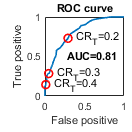

load("data\fig2_hypothesis.mat");

figure('Color',[1 1 1]);
set(gcf,'unit','centimeters','position', figsize);
set(gca,'Position', figpos);
set(gcf,'Visible','on');
p = plot(fplist,tplist);
hold on;
p.LineWidth = 1.2;
p = plot(0.010416666666667, 0.144230769230769, 'or');
text(0.010416666666667 + 0.1, 0.144230769230769, "CR_T=0.4");
hold on;
p.LineWidth = 1.2;
p = plot(0.046875000000000, 0.283653846153846, 'or');
text(0.046875000000000 + 0.1, 0.283653846153846, "CR_T=0.3");
hold on;
p.LineWidth = 1.2;
p = plot(0.291666666666667, 0.730769230769231, 'or');
text(0.291666666666667 + 0.1, 0.730769230769231, "CR_T=0.2");
hold on;
p.LineWidth = 1.2;
% textscatter(0.010416666666667, 0.144230769230769, "CRlim=0.4");
t = text(0.28, 0.5, ['AUC=' num2str(AUC, '%.2f')]);
t.FontWeight = 'bold';
xlim([0 1]);
ylabel("True positive");
xlabel("False positive");
title("ROC curve");

m_CRESN20 = mean(CRlistESN20)

m_CRESN20 = 0.5459

disp(m_CRESN20);

    0.5459

